# A Model for Glass Identification Given Chemical Composition

## A Comparision between Random Forests and Decision Trees

**Ayliah Fani - 200044837**

## 1. Data Selection

% Data comes from: https://archive.ics.uci.edu/ml/datasets/glass+identification
glass_data_import = readtable("glass.csv");

## **2. Data Preparation**

### **A. Cleaning**

% remove id column & reindex
glass = glass_data_import(:,2:end);

% rename columns
glass.Properties.VariableNames = {'refractive_index' 'Na' 'Mg' 'Al' 'Si' 'K' 'Ca' 'Ba' 'Fe' 'type_of_glass'};

% check for missing values
missingvalues = sum(ismissing(glass))

missingvalues =      0     0     0     0     0     0     0     0     0     0



% split predictors and response
X = glass{:,1:end-1};
Y = glass{:,end};

% look at response
tabulate(glass.type_of_glass)

  Value    Count   Percent
      1       70     32.71%
      2       76     35.51%
      3       17      7.94%
      4        0      0.00%
      5       13      6.07%
      6        9      4.21%
      7       29     13.55%


There is quite a bit of class imbalance that needs to be taken into consideration.

### **B. Descriptive Statistics**

% % statistical summary of each variable
% format compact
% summary(glass);

### **C. Visualisation**

allX = [glass.type_of_glass,glass.type_of_glass,glass.type_of_glass,glass.type_of_glass,
    glass.type_of_glass,glass.type_of_glass,glass.type_of_glass,glass.type_of_glass,
    glass.type_of_glass];
allY = [glass.refractive_index, glass.Na, glass.Mg, glass.Al, glass.Si, glass.K, glass.Ca, 
    glass.Ba, glass.Fe];
titles = glass.Properties.VariableNames;

% % scatter plots of refractive index and glass oxide contents of each glass type
% for k=1:size(allX,2)
%     figure(k)
%     scatter(allX(:,k),allY(:,k))
%     title (titles(k))
%     xlabel('glass type')
%     ylabel(titles(k))
% end
% 
% % box plots of refractive index and glass oxide content for each glass type
% for k=1:size(allX,2)
%     figure(k)
%     boxplot(allY(:,k),glass.type_of_glass)
%     title (titles(k))
%     xlabel('glass type')
%     ylabel(titles(k))
% end

from the box plots I might look into removing outliers since some ML techniques are sensitive to them.

### **D. Partitioning the Data**

[m,n] = size(glass) ; 
idx = randperm(m) ;  % shuffle the rows 

%training data
train = glass{idx(1:round(m*0.70)),:}  ;
train_X = train(:,1:end-1);
train_Y = train(:,end);

%testing data
test = glass{idx(round(m*0.70)+1:round(m*0.85)),:} ;
test_X = test(:,1:end-1);
test_Y = test(:,end);

% validation data
val = glass{idx(round(m*0.85)+1:end),:} ;
val_X = val(:,1:end-1);
val_Y = val(:,end);

% 
% rng(1)                      % For reproducibility
% part = cvpartition(Y,'Holdout',0.2);
% 
% % training data
% istrain = training(part);   % Data for fitting
% train_X = X(istrain,:);
% train_Y = Y(istrain);
% 
% % testing data
% istest = test(part);        % Data for quality assessment
% test_X = X(istest,:);
% test_Y = Y(istest);
% 
% % look at count of classes present in the training set
% tabulate(train_Y)

`rng() `was changed multiple times to find the version which produced the best model and reproducability.

the percent holdout for `cvpartition` was also changed multiple times in order to find the percentage which yielded the best training model.

## **3. Model Selection**

### **A. Naïve Bayes**

Since variance is 0 for many predictors in the samples, Naïve Bayes cannot be used.

### B. Random Forests

#### i. Model Training

Several classes are quite a low percentage of the data. This imbalance indicates that `RUSBoost` is an appropriate algorithm to use since the data is multiclass and skewed, but it is not within the scope of this course therefore `Bag` (Random Forests) will be used.

rng(1)                    % For reproducibility
% N = sum(istrain);       % Number of observations in the training sample
N = size(train,1);
dt_op = templateTree('MaxNumSplits',N, 'Reproducible', true);
rf_mdl = fitcensemble(train_X,train_Y,'Method','Bag', ...
    'NumLearningCycles',200,'Learners',dt_op);

#### ii. Evaluate Performance

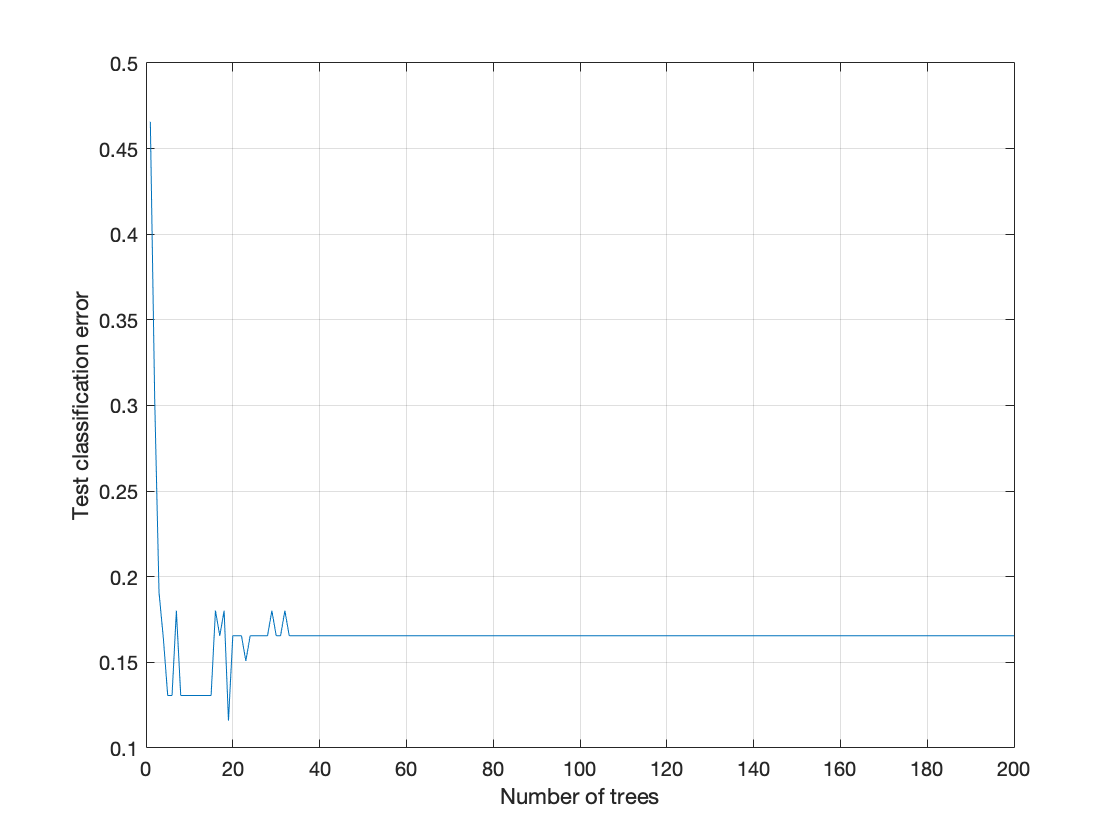

% Plot misclassification/loss against the number of trees in the ensemble.
figure;
plot(loss(rf_mdl,test_X,test_Y,'mode','cumulative'));
grid on;
xlabel('Number of trees');
ylabel('Test classification error');

title ('Misclassification ')

The ensemble reaches the minimum error between 130-134 trees with an error of ~26%

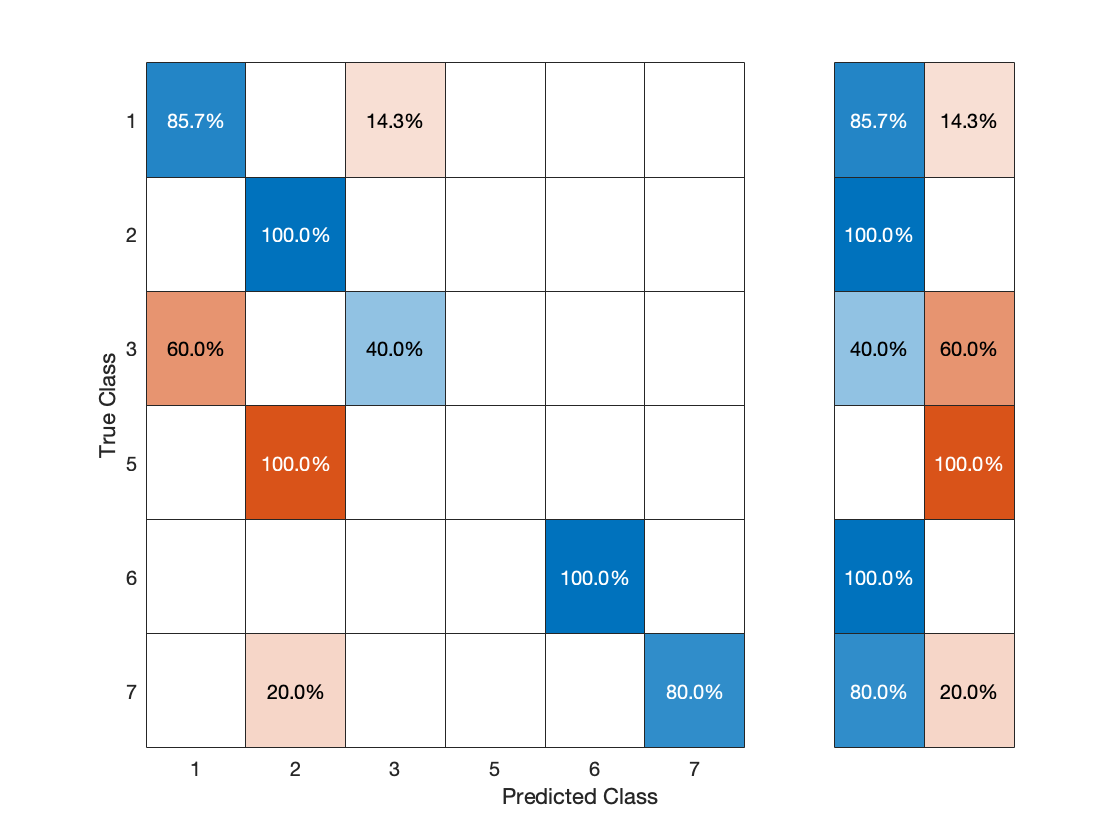

% confusion matrix
Yfit = predict(rf_mdl, test_X);
confusionchart(test_Y,Yfit,'Normalization','row-normalized','RowSummary','row-normalized')


% loss
rf_loss = loss(rf_mdl, test_X, test_Y)

rf_loss = 0.1655

**Cross Validation Error**

Generate a five-fold cross-validated ensemble.

% Perform cross-validation
rf_cv= crossval(rf_mdl, 'KFold', 5);

Examine the cross-validation loss as a function of the number of trees in the ensemble.

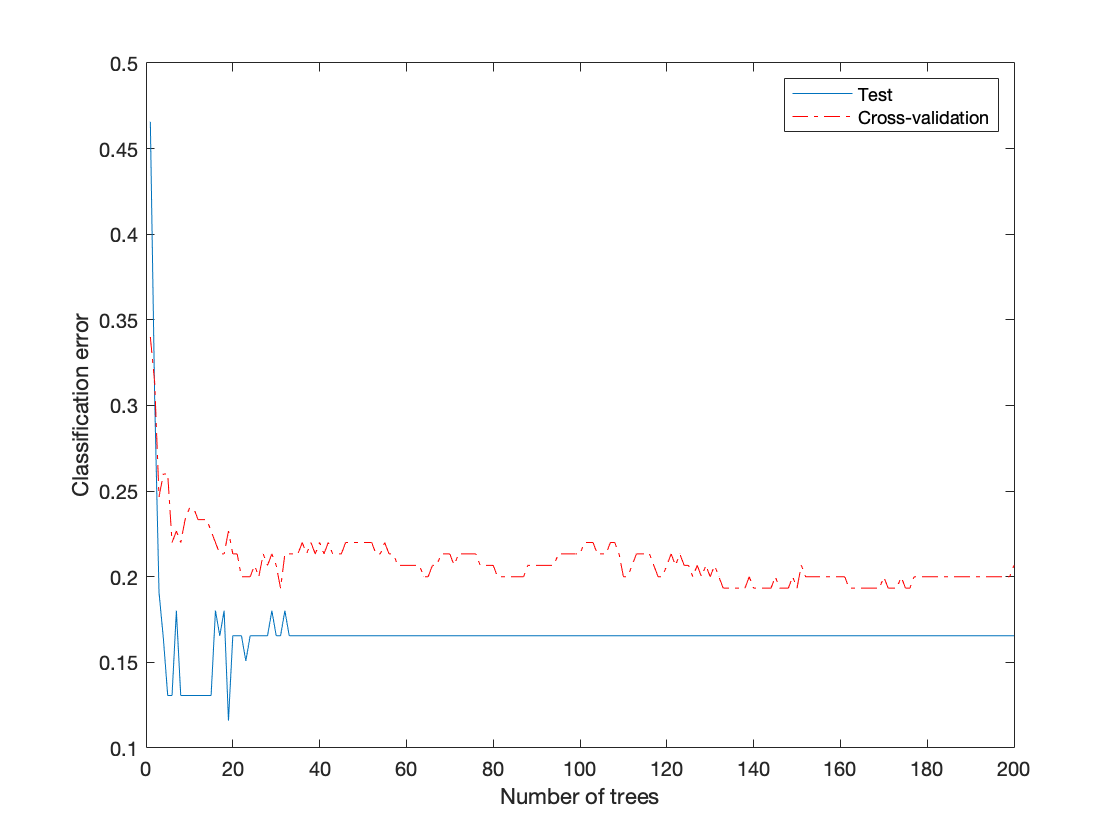

figure
plot(loss(rf_mdl,test_X,test_Y,'mode','cumulative'))
hold on
plot(kfoldLoss(rf_cv,'mode','cumulative'),'r-.')
hold off
xlabel('Number of trees')
ylabel('Classification error')
legend('Test','Cross-validation','Location','NE')

Cross validating gives comparable estimates to those of the independent set.

% Compute validation predictions
[validationPredictions, validationScores] = kfoldPredict(rf_cv);

% Compute validation accuracy
validationAccuracy = 1 - kfoldLoss(rf_cv, 'LossFun', 'ClassifError');

**Out-of-Bag Error**

Generate the loss curve for out-of-bag estimates, and plot it along with the other curves.

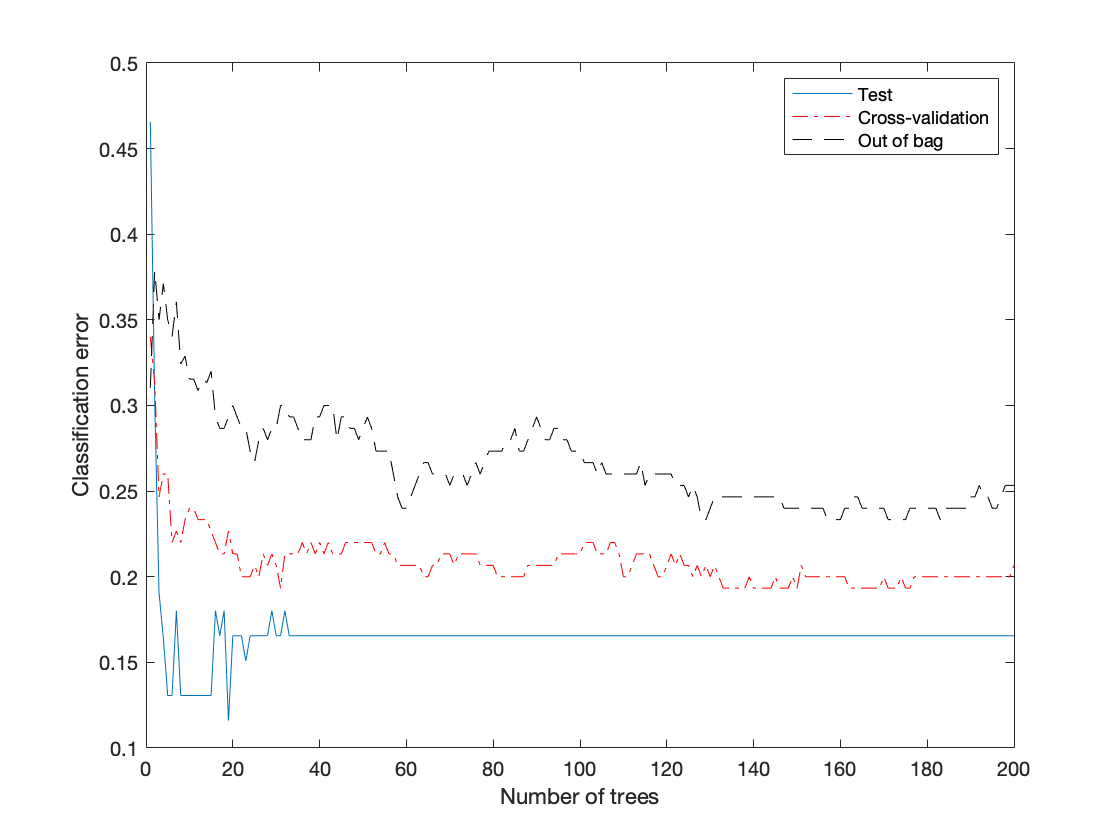

% out of bag estimates
figure
plot(loss(rf_mdl,test_X,test_Y,'mode','cumulative'))
hold on
plot(kfoldLoss(rf_cv,'mode','cumulative'),'r-.')
plot(oobLoss(rf_mdl,'mode','cumulative'),'k--')
hold off
xlabel('Number of trees')
ylabel('Classification error')
legend('Test','Cross-validation','Out of bag','Location','NE')

#### iii. Optimisation

The curve contains a minimum cross-validated misclassification rate occurring at the optimal number of trees in the ensemble.

[minErr, minErridx] = min(loss(rf_mdl,test_X,test_Y,'mode','cumulative'));

fprintf('\nMinimum classification error = %0.5f',minErr)


Minimum classification error = 0.11600

fprintf('\nOptimal Num. Trees = %d',minErridx);


Optimal Num. Trees = 19

re-train the model with those values

#### iv. Final Preditions

Create a predictive random forest based on the optimal hyperparameters and the entire training set.

rng(1)
tFinal = templateTree('MaxNumSplits',N, 'Reproducible', true);
rf_Final = fitcensemble(train_X,train_Y,'Method', 'Bag', 'NumLearningCycles',minErridx,...
    'Learners',tFinal);

make predictions with the new model

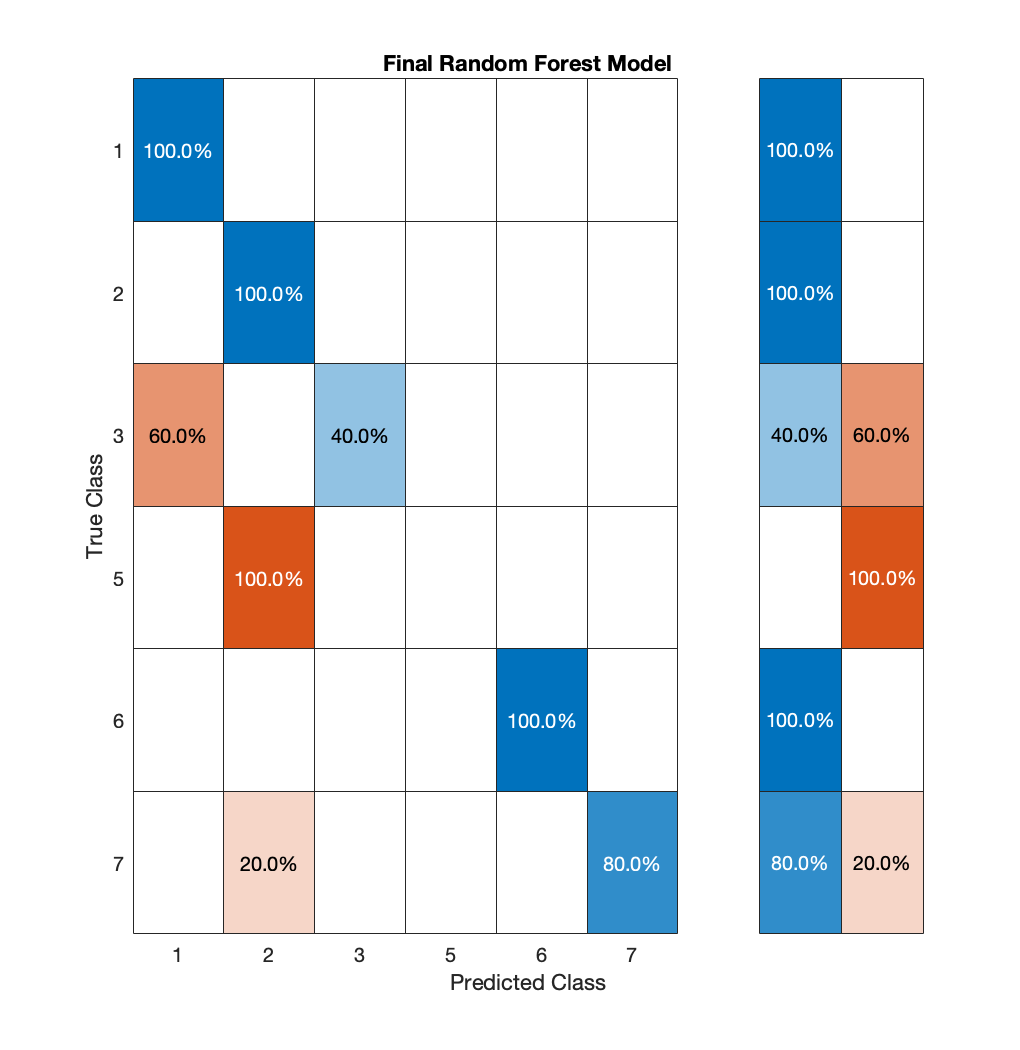

% confusion matrix
Yfit_final = predict(rf_Final, test_X);
confusionchart(test_Y,Yfit_final,'Normalization','row-normalized','RowSummary','row-normalized', ...

    'Title','Final Random Forest Model')

% loss
rf_loss_final = loss(rf_Final, test_X, test_Y)

rf_loss_final = 0.1160

# C. Decision Trees

#### **i. Model Training**

% grow a classification tree fromt he training set
dt_mdl = fitctree(train_X, train_Y, 'Reproducible',true);

% view the classification tree
% %view(dt_mdl,'Mode','graph');

#### ii. Evaluate Performance

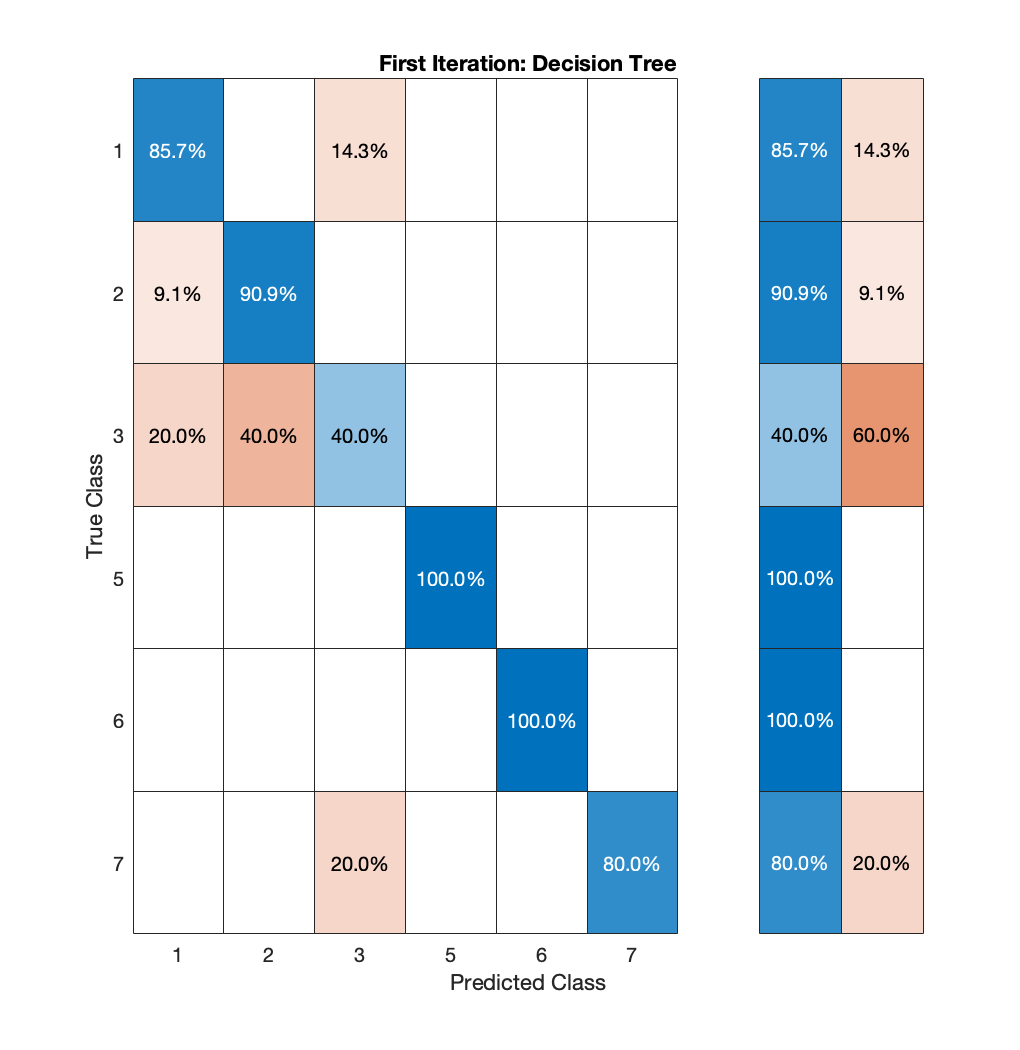

% confusion matrix
dt_fit = predict(dt_mdl, test_X);
confusionchart(test_Y,dt_fit,'Normalization','row-normalized','RowSummary','row-normalized', ...

    'Title','First Iteration: Decision Tree')

% calculate resubstitution/In-sample classification error
resuberror = resubLoss(dt_mdl)

resuberror = 0.1400


% loss
dt_loss = loss(dt_mdl, test_X, test_Y)

dt_loss = 0.1522

**Cross validation:**

% Perform cross-validation
dt_cv = crossval(dt_mdl, 'KFold', 5);
dt_cvloss = kfoldLoss(dt_cv)

dt_cvloss = 0.3000


% Compute validation predictions
[validationPredictions, validationScores] = kfoldPredict(dt_cv);

% Compute validation accuracy
validationAccuracy = 1 - kfoldLoss(dt_cv, 'LossFun', 'ClassifError');

**Examine the classification error for each subtree:**

Examine the training sample classification error for each subtree (or pruning level) excluding the highest level.

m = max(dt_mdl.PruneList) - 1;
trainLoss = resubLoss(dt_mdl,'SubTrees',0:m)

trainLoss =     0.1400
    0.1733
    0.2067
    0.2467
    0.3067
    0.3600


- The full, unpruned tree misclassifies about 16% of the training observations.

- The tree pruned to level 1 misclassifies about 18% of the training observations.

- The tree pruned to a stump misclassifies about 36% of the training observations.

Examine the validation sample classification error at each level excluding the highest level.

valLoss = loss(dt_mdl,val_X,val_Y,'SubTrees',0:m)

valLoss =     0.4179
    0.4179
    0.4179
    0.4529
    0.4632
    0.4999


- The full, unpruned tree misclassifies about 22% of the validation observations.

- The tree pruned to level 1 misclassifies about 23% of the validation observations.

- The tree pruned to level 2 (i.e., a stump) misclassifies about 46% of the validation observations.

From these observations we can look at pruning the tree to level 1 since there is not a significant increase in misclassification between the unpruned tree and the tree pruned to level 1. Even though the error increases, pruning is suitable since it simplifies the model and prevents overfitting.

To balance model complexity and out-of-sample performance, we can consider pruning `Mdl` to level 1 and see how the response is to the test data.

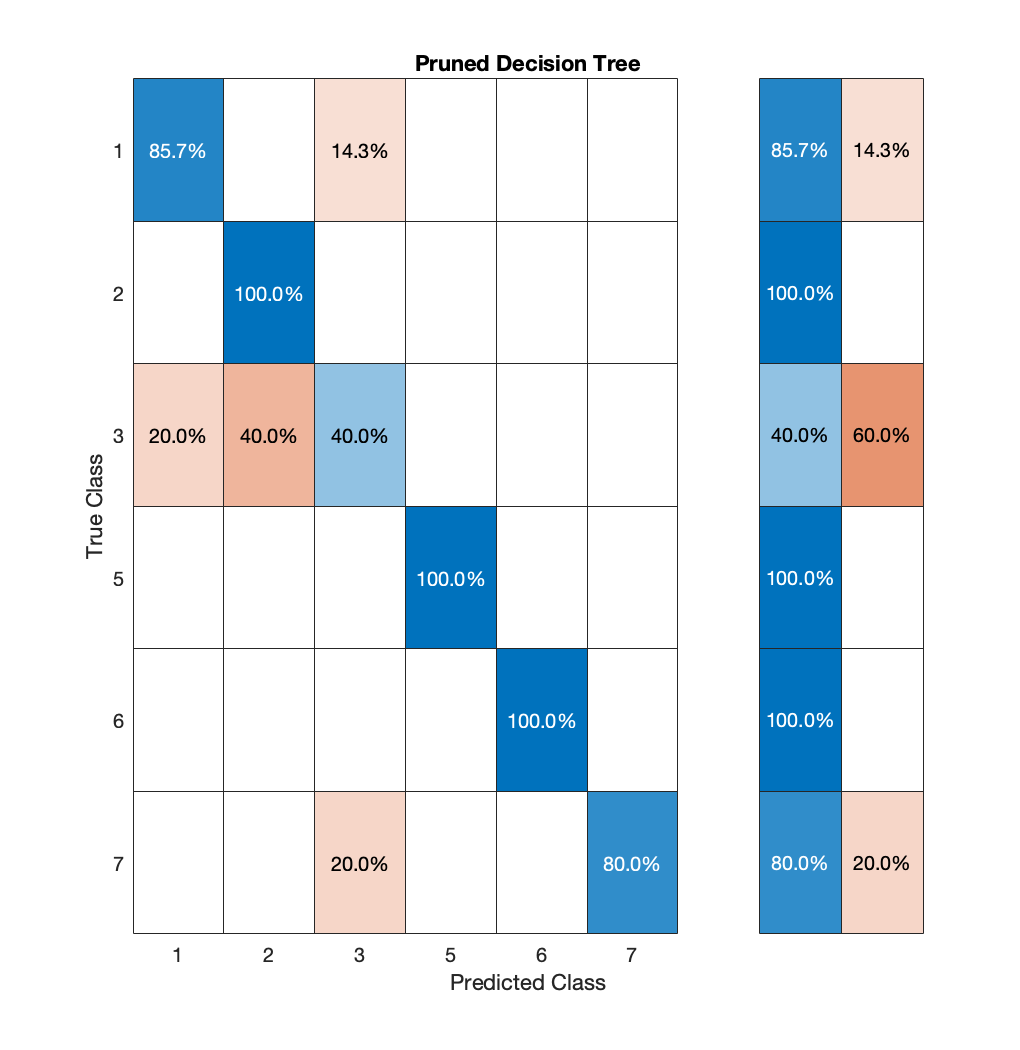

% Prune the model to level 1
dt_pruned = prune(dt_mdl,'Level',1);
% view(pruneMdl,'Mode','graph')

% confusion matrix
dt_prunePred= predict(dt_pruned, test_X);
confusionchart(test_Y,dt_prunePred,'Normalization','row-normalized','RowSummary','row-normalized', 'Title','Pruned Decision Tree')


% loss
dt_pruneLoss = loss(dt_pruned, test_X, test_Y)

dt_pruneLoss = 0.1189

[citation](https://www.mathworks.com/help/stats/classificationtree.resubloss.html#bunffiu-1)

#### **iii. Optimisation**

% dt_op = fitctree(test_X,test_Y,'OptimizeHyperparameters','auto');

**Select appropriate tree depth:**

Generate a spaced set of values from 1 through 30 via `leaves `that represents the minimum number of observations per leaf node.

Create cross-validated classification trees for the data and use to plot the cross-validated error versus minimum leaf size.

|======================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |  MinLeafSize |
|      | result |             | runtime     | (observed)  | (estim.)    |              |
|======================================================================================|
|    1 | Best   |     0.40625 |    0.057041 |     0.40625 |     0.40625 |            4 |


|    2 | Accept |       0.625 |    0.073119 |     0.40625 |     0.42419 |           12 |


|    3 | Accept |     0.46875 |    0.054917 |     0.40625 |     0.40627 |            2 |


|    4 | Accept |     0.46875 |    0.064365 |     0.40625 |     0.40627 |            1 |


|    5 | Accept |     0.46875 |    0.082027 |     0.40625 |     0.42268 |            3 |


|    6 | Accept |     0.40625 |     0.06893 |     0.40625 |     0.40625 |            5 |


|    7 | Best   |       0.375 |    0.055532 |       0.375 |     0.38827 |            6 |


|    8 | Accept |       0.375 |    0.049314 |       0.375 |     0.37501 |            6 |


|    9 | Accept |       0.375 |    0.095878 |       0.375 |     0.37501 |            7 |


|   10 | Accept |       0.375 |     0.06135 |       0.375 |     0.37501 |            7 |


|   11 | Accept |       0.375 |    0.051962 |       0.375 |       0.375 |            6 |


|   12 | Accept |       0.375 |    0.081848 |       0.375 |       0.375 |            7 |


|   13 | Accept |       0.375 |    0.061383 |       0.375 |       0.375 |            6 |


|   14 | Accept |      0.4375 |    0.069358 |       0.375 |       0.375 |            8 |


|   15 | Accept |       0.375 |     0.80653 |       0.375 |       0.375 |            7 |


|   16 | Accept |     0.65625 |     0.08827 |       0.375 |       0.375 |           16 |


|   17 | Accept |         0.5 |     0.06275 |       0.375 |       0.375 |           10 |


|   18 | Accept |     0.65625 |    0.050811 |       0.375 |       0.375 |           14 |


|   19 | Accept |     0.46875 |    0.062548 |       0.375 |       0.375 |            9 |


|   20 | Accept |      0.5625 |    0.074049 |       0.375 |     0.37499 |           11 |


|======================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |  MinLeafSize |
|      | result |             | runtime     | (observed)  | (estim.)    |              |
|======================================================================================|
|   21 | Accept |     0.65625 |     0.07645 |       0.375 |     0.37499 |           15 |


|   22 | Accept |        0.75 |    0.087058 |       0.375 |     0.37517 |           13 |


|   23 | Accept |       0.375 |     0.10237 |       0.375 |     0.37505 |            7 |


|   24 | Accept |       0.375 |    0.065732 |       0.375 |     0.37506 |            6 |


|   25 | Accept |       0.375 |    0.092865 |       0.375 |       0.375 |            6 |


|   26 | Accept |       0.375 |    0.076504 |       0.375 |       0.375 |            6 |


|   27 | Accept |       0.375 |    0.069665 |       0.375 |       0.375 |            6 |


|   28 | Accept |       0.375 |    0.086494 |       0.375 |       0.375 |            7 |


|   29 | Accept |       0.375 |     0.10772 |       0.375 |       0.375 |            6 |


|   30 | Accept |     0.46875 |     0.08021 |       0.375 |       0.375 |            9 |


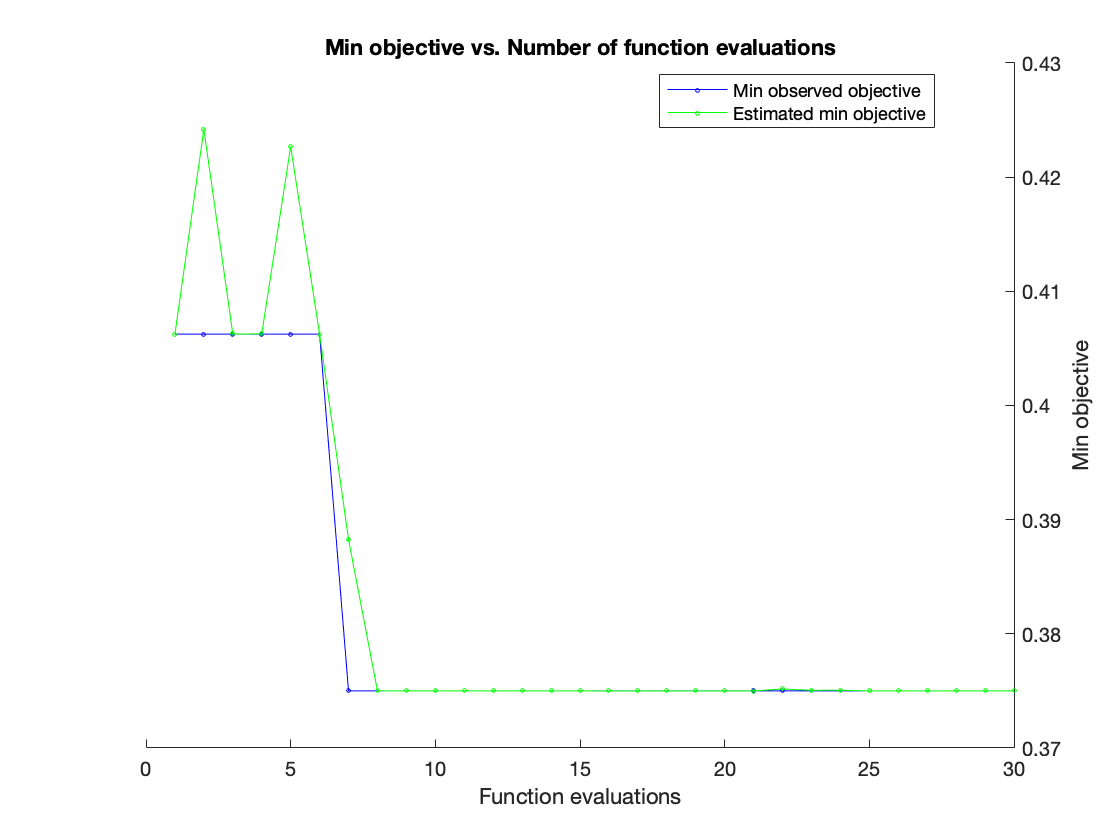

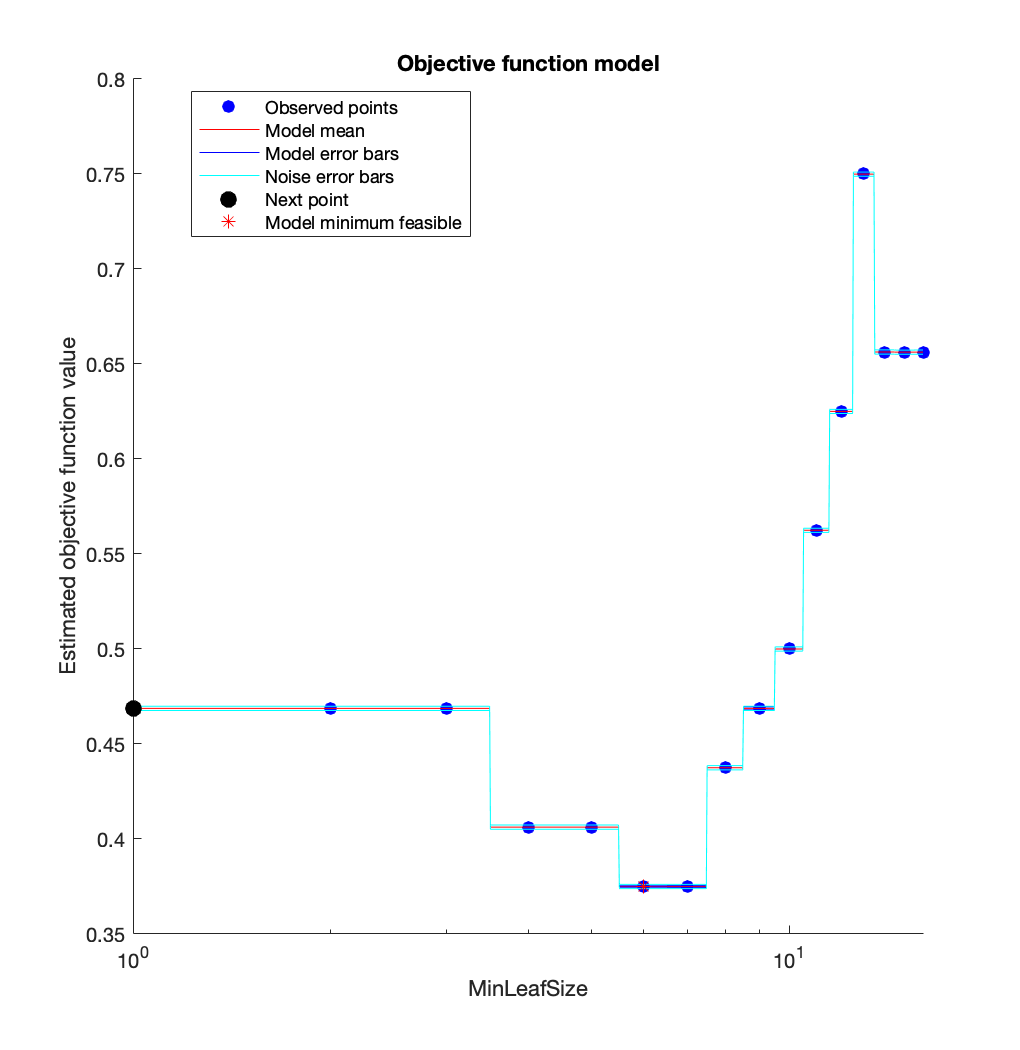


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 30 reached.
Total function evaluations: 30
Total elapsed time: 46.4508 seconds
Total objective function evaluation time: 2.9171

Best observed feasible point:
    MinLeafSize
    ___________

         6     

Observed objective function value = 0.375
Estimated objective function value = 0.375
Function evaluation time = 0.055532

Best estimated feasible point (according to models):
    MinLeafSize
    ___________

         6     

Estimated objective function value = 0.375
Estimated function evaluation time = 0.07719



leaves = [1:30];

rng('default')
N = numel(leaves);
err = zeros(N,1);

for n=1:N
    dt_op = fitctree(train_X,train_Y,'CrossVal','On',...
        'MinLeafSize',leaves(n));
    err(n) = kfoldLoss(dt_op);
end

% plot cross-val error of each model against respective min. leaf size
plot(leaves,err);
xlabel('Min Leaf Size');
ylabel('cross-validated error');

From the graph the best leaf size is approximately .

Compare the optimal tree with at least 5 observations per leaf with the default tree, which uses `10` observations per parent node and `1` observation per leaf.

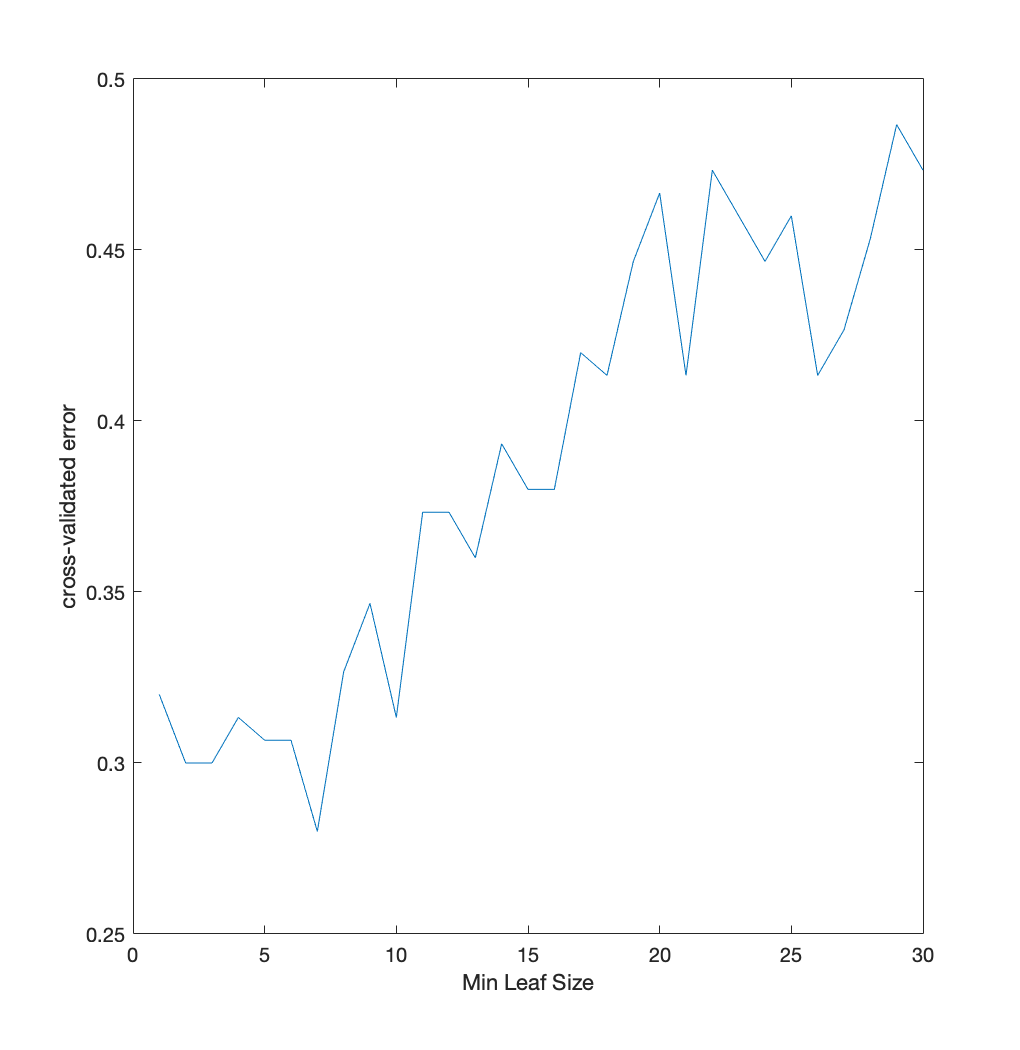

view(dt_mdl,'Mode','Graph');

OptimalTree = fitctree(train_X,train_Y,'MinLeafSize',5);

view(OptimalTree,'mode','graph');

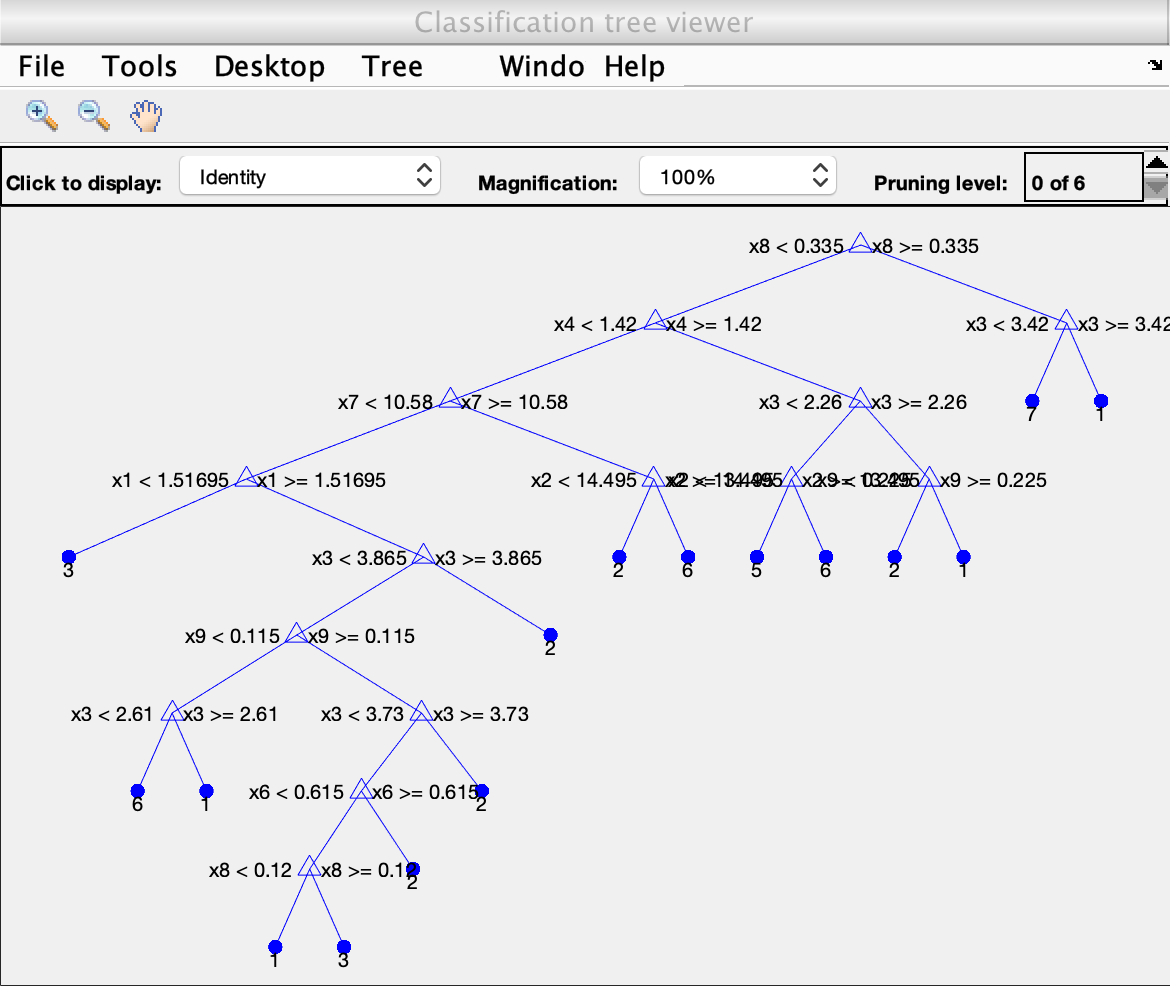

resubOpt = resubLoss(OptimalTree);

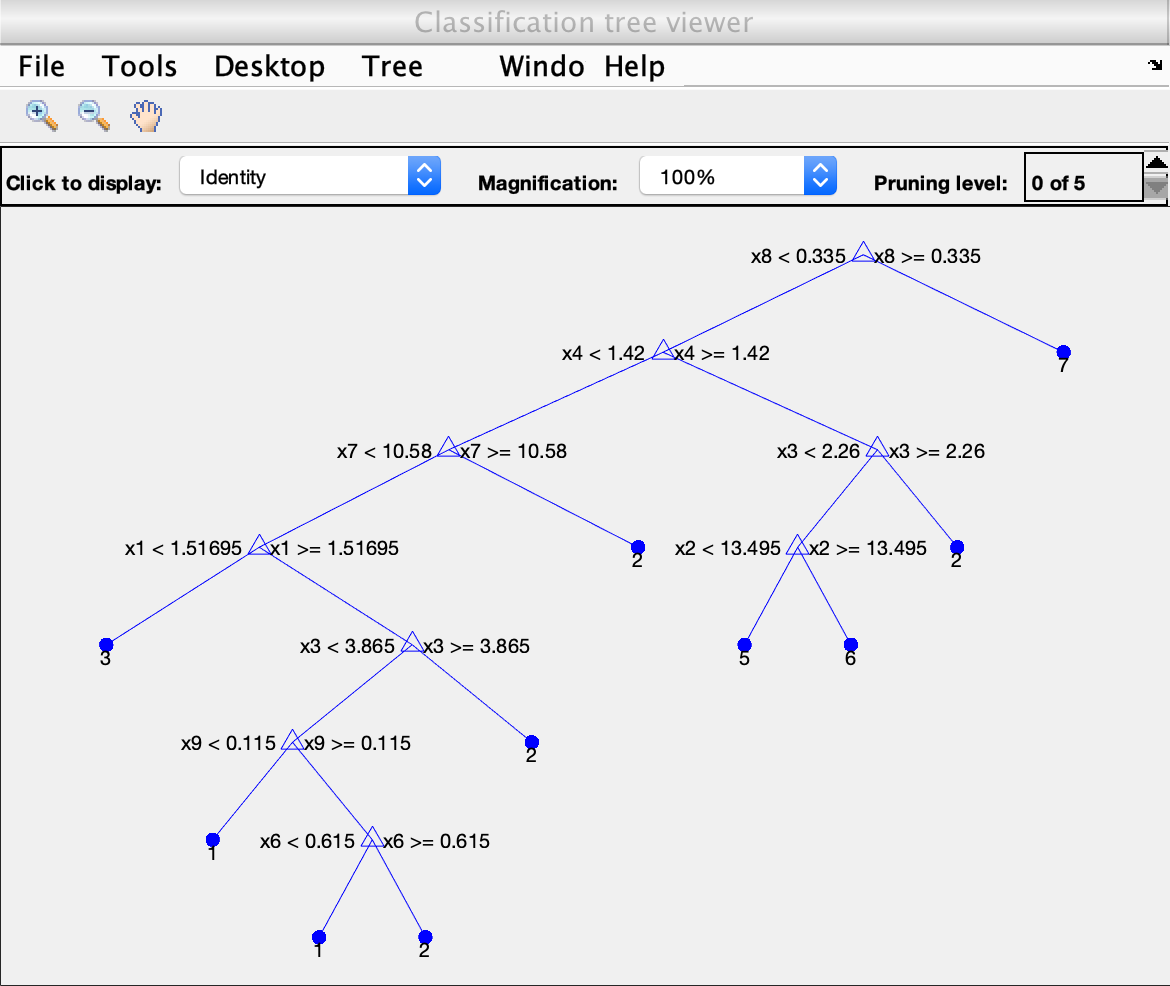

lossOpt = kfoldLoss(crossval(OptimalTree));

resubDefault = resubLoss(dt_mdl);

lossDefault = kfoldLoss(crossval(dt_mdl));

resubOpt,resubDefault,lossOpt,lossDefault

The optimal tree is smaller and gives a higher error resub and loss error. 

[citation](https://www.mathworks.com/help/stats/improving-classification-trees-and-regression-trees.html#bsx6u4u)

#### iv. Final Predictions

resubOpt = 0.1867

resubDefault = 0.1400

lossOpt = 0.3000

lossDefault = 0.3000